%% Полный цикл обработки сигнала в OFDM системе
% Добавить в начало:
if ~license('test', 'communication_toolbox')
    error('Communications Toolbox is required.');
end
clear all; clc;

%% Определение параметров модели
ofdm_params = ofdm_config();
channel_params = channel_config();

%% Генерация текстового сообщения
textMessage = 'HELLO WORLD THIS IS A TEST MESSAGE.';
disp('Исходный текст:');

Исходный текст:


disp(textMessage);

HELLO WORLD THIS IS A TEST MESSAGE.



% Практика 1: Знаковое кодирование
bits = symbolEncoder(textMessage);
disp('Исходные биты (первые 20):');

Исходные биты (первые 20):


disp(bits(1:min(20, end)));

     1     0     0     0     0     1     0     1     1     1     1     0     1     0     0     1     0     1     1     0




% Практика 2: Сверточное кодирование
encoded_bits = convolutionalEncoder(bits);
disp('Закодированные биты (первые 20):');

Закодированные биты (первые 20):


disp(encoded_bits(1:min(20, end)));

     1     1     1     0     1     1     1     1     0     0     1     0     0     1     0     0     1     0     1     0




% Практика 3: Перемежение
interleaved_bits = interleaver(encoded_bits);

% Практика 4: QPSK модуляция
qpsk_symbols = qpskModulator(interleaved_bits);

% Практика 5: OFDM модуляция
ofdm_symbol = ofdmModulator(qpsk_symbols, ofdm_params);

% Практика 6: Многолучевой канал
received_signal = multipathChannel(ofdm_symbol, channel_params);


% Практика 7: OFDM демодуляция
qpsk_symbols_rx = ofdmDemodulator(received_signal);

% Практика 8: QPSK демодуляция
received_interleaved_bits = qpskDemodulator(qpsk_symbols_rx);

% Практика 9: Обратное перемежение
received_encoded_bits = deinterleaver(received_interleaved_bits);

% Практика 10: Декодирование Витерби
decoded_bits = viterbiDecoder(received_encoded_bits);

% Практика 11: Знаковое декодирование
received_text = symbolDecoder(decoded_bits);
ber_approx = sum(bits(1:length(decoded_bits)) ~= decoded_bits) / length(decoded_bits); 
disp('Полученный текст:');

Полученный текст:


if isequal(textMessage, received_text)
    disp(received_text);
else
    disp('Test FAILED: Decoded message does not match original.');
    disp(['Original Message:  ', textMessage]);
    disp(['Decoded Message:   ', received_text]);
    ber_approx = sum(bits(1:length(decoded_bits)) ~= decoded_bits) / length(decoded_bits);
    disp(['Approximate BER before symbol decoder: ', num2str(ber_approx)]);
   
end

Test FAILED: Decoded message does not match original.


Original Message:  HELLO WORLD THIS IS A TEST MESSAGE.


Decoded Message:   HELLO WORLD THQm IS A TEST MESSAGE.


Approximate BER before symbol decoder: 0.0095238


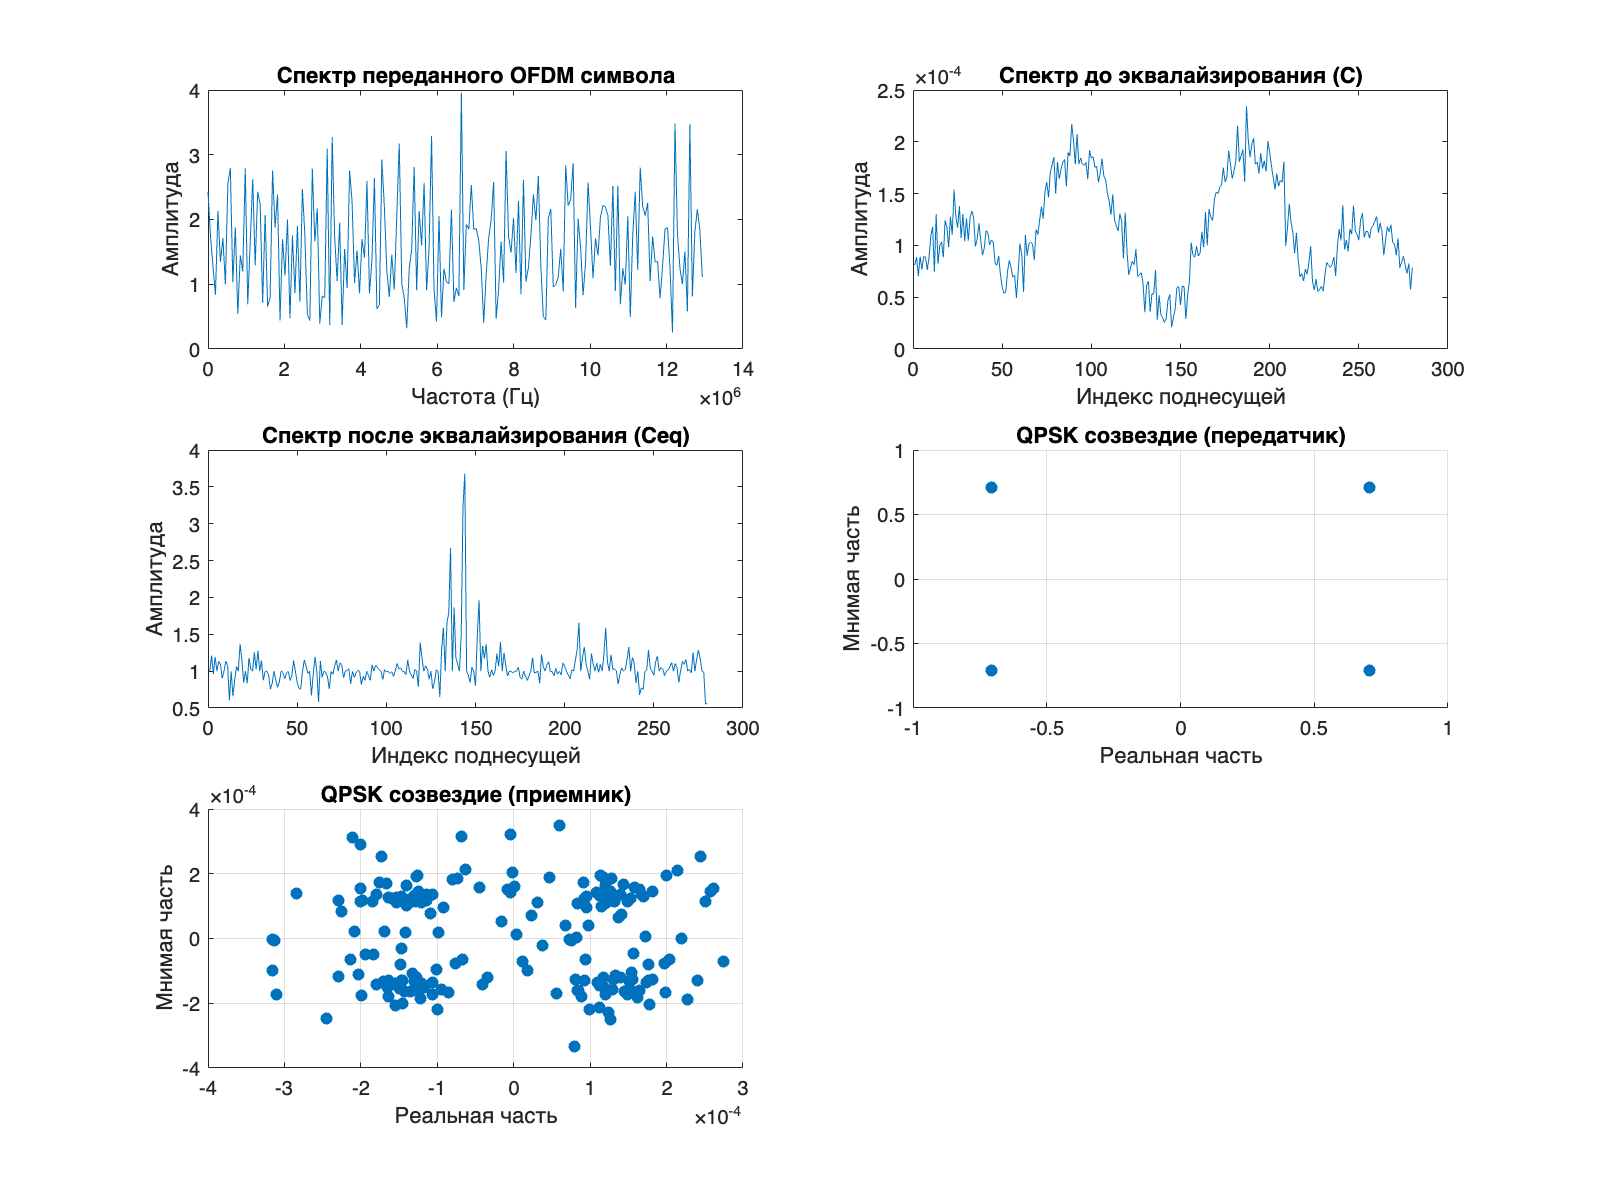


%% Построение графиков
figure('Name', 'Анализ сигналов');

% Спектр переданного OFDM символа
subplot(3, 2, 1);
ofdm_freq = fft(ofdm_symbol(getappdata(0, 'cpLength') + 1:end));
f = (0:length(ofdm_freq)-1) * (channel_params.bandwidth / length(ofdm_freq));
plot(f, abs(ofdm_freq));
title('Спектр переданного OFDM символа');
xlabel('Частота (Гц)');
ylabel('Амплитуда');

% Спектр принятого сигнала до эквалайзирования
C = getappdata(0, 'ofdmSpectrum_C');
subplot(3, 2, 2);
plot(1:length(C), abs(C));
title('Спектр до эквалайзирования (C)');
xlabel('Индекс поднесущей');
ylabel('Амплитуда');

% Спектр после эквалайзирования
Ceq = getappdata(0, 'equalizedSpectrum_Ceq');
subplot(3, 2, 3);
plot(1:length(Ceq), abs(Ceq));
title('Спектр после эквалайзирования (Ceq)');
xlabel('Индекс поднесущей');
ylabel('Амплитуда');

% QPSK созвездие в передатчике
subplot(3, 2, 4);
scatter(real(qpsk_symbols), imag(qpsk_symbols), 'filled');
title('QPSK созвездие (передатчик)');
xlabel('Реальная часть');
ylabel('Мнимая часть');
grid on;

% QPSK созвездие в приемнике
subplot(3, 2, 5);
scatter(real(qpsk_symbols_rx), imag(qpsk_symbols_rx), 'filled');
title('QPSK созвездие (приемник)');
xlabel('Реальная часть');
ylabel('Мнимая часть');
grid on;

set(gcf, 'Position', [100, 100, 800, 600]);